## **Problema 2:**

Crea un código del tipo function cuyos inputs sean la matriz de adyacencia de un grafo $G$ y sus outputs sean un array de carácteres indicando si el grafo es conexo o no.

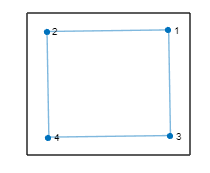

% Ejemplo conexo
A = [
    0 1 1 0
    1 0 0 1
    1 0 0 1
    0 1 1 0
];

G = graph(A);
figure
plot(G)


resultado = comprobar_conexo(A);
disp(resultado);

El grafo es conexo


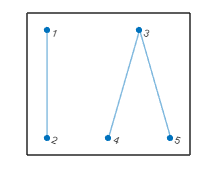


% ejemplo no conexo
B = [
    0 1 0 0 0;
    1 0 0 0 0;
    0 0 0 1 1;
    0 0 1 0 0;
    0 0 1 0 0;
];

P = graph(B);
figure
plot(P)


res_B = comprobar_conexo(B);
disp(res_B);

El grafo no es conexo


function res = comprobar_conexo(m_ady) % Esta funcion comprueba si e grafo es conexo o no.
    [fil, col] = size(m_ady);

    if fil ~= col || ~isequal(m_ady, m_ady')
        error('Matriz de adyacencia no válida.');
    end

    if comprobar_coneccion(m_ady)
        res = 'El grafo es conexo';
    else
        res = 'El grafo no es conexo';
    end   

end

% La función verifica si es posible llegar a todos los nodos del grafo desde
% un nodo de inicio dado.
function conectividad = comprobar_coneccion(grafo)
    
    v = size(grafo, 1);
    visto = false(1, v);
    cola = 1;
    
    % Se sejecuta mientras siga haya nodos pendientes de explorar en la cola.
    while ~isempty(cola)

        v_actual = cola(1);
        cola = cola(2:end);

        visto(v_actual) = true;
        
        No_visto = find(grafo(v_actual, :) & ~visto);
        
        cola = [cola, No_visto];

    end

    conectividad = all(visto);
end